# Problem 3: Damped Oscillations

note that damped_oscillator is defined as:

damped_oscillator(omega0, gamma, theta0, thetadot0, grph)

## (a) Test plot - Undamped case

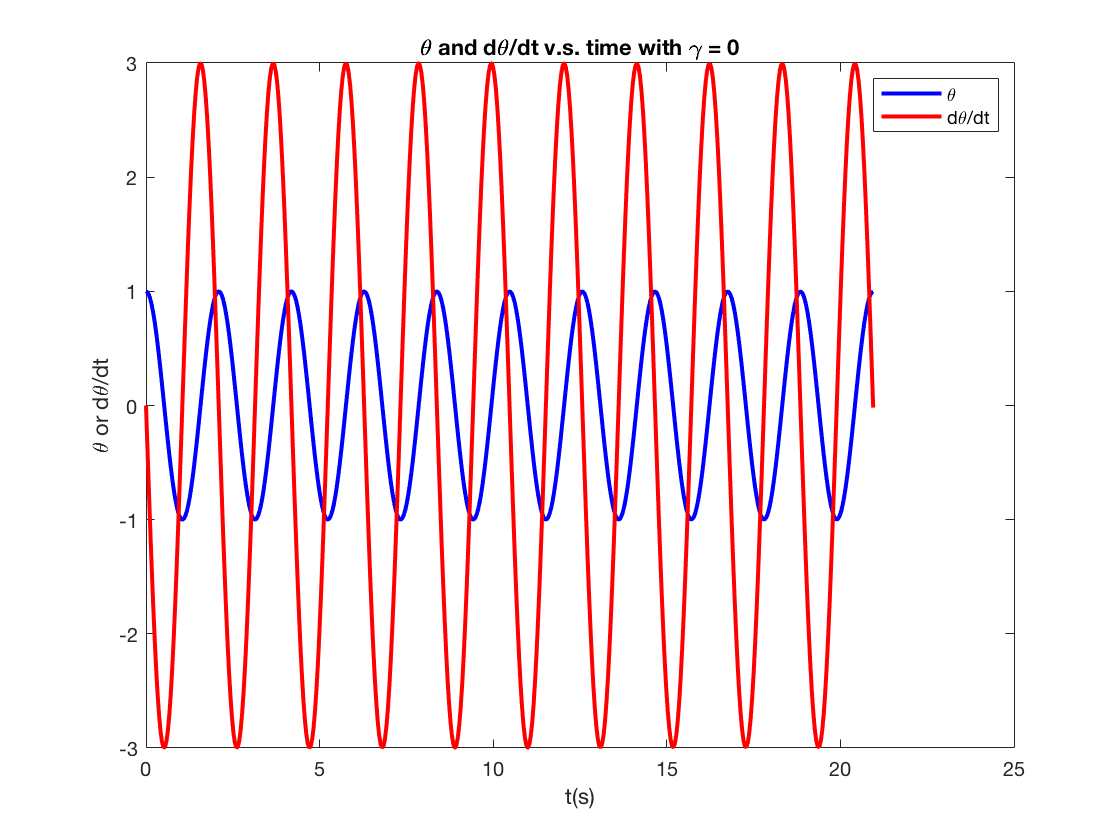

[T, sol] = damped_oscillator(3,0,1,0);

T_undamped = T;
omega_undamped = 2*pi/T_undamped;
disp(['Undamped period is ' num2str(T_undamped),', freq is ',num2str(omega_undamped)])

Undamped period is 1.9947, freq is 3.15


## (b) (c) Damping v.s. Undamped and Energy plot

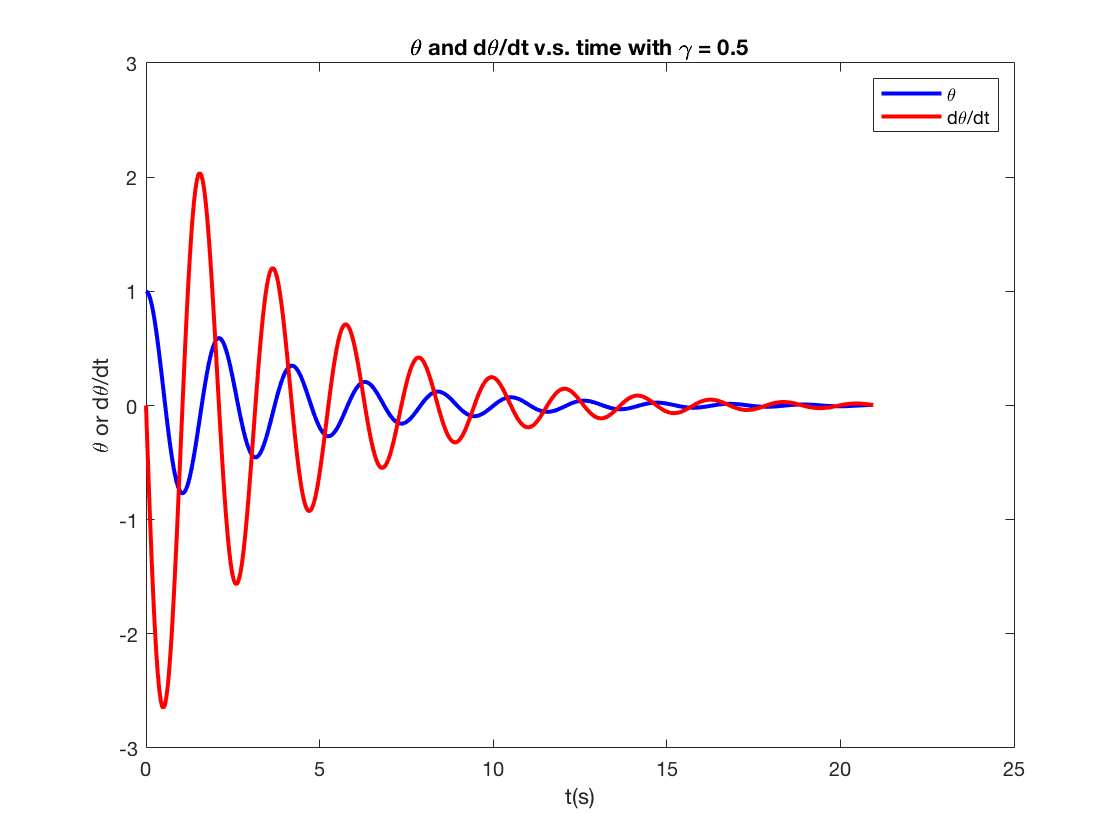

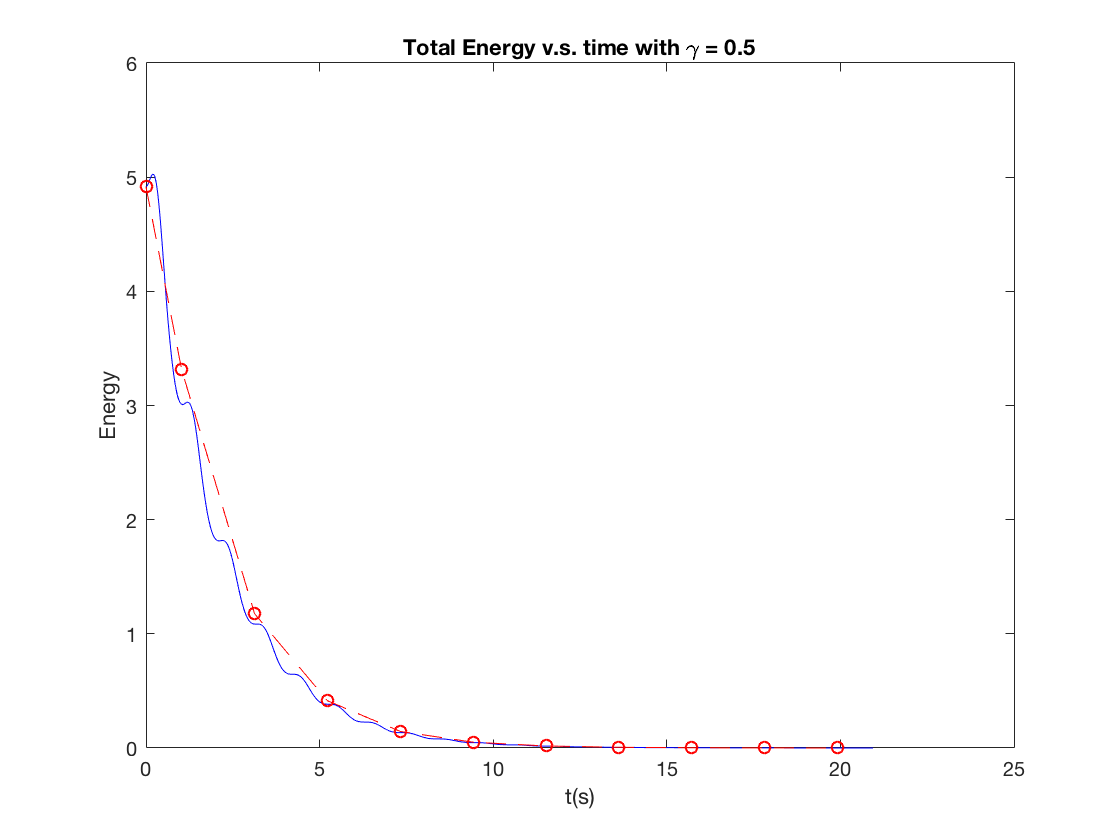

T = 2.0944

T ratio = 1.05, ang. freq. ratio is 0.9524


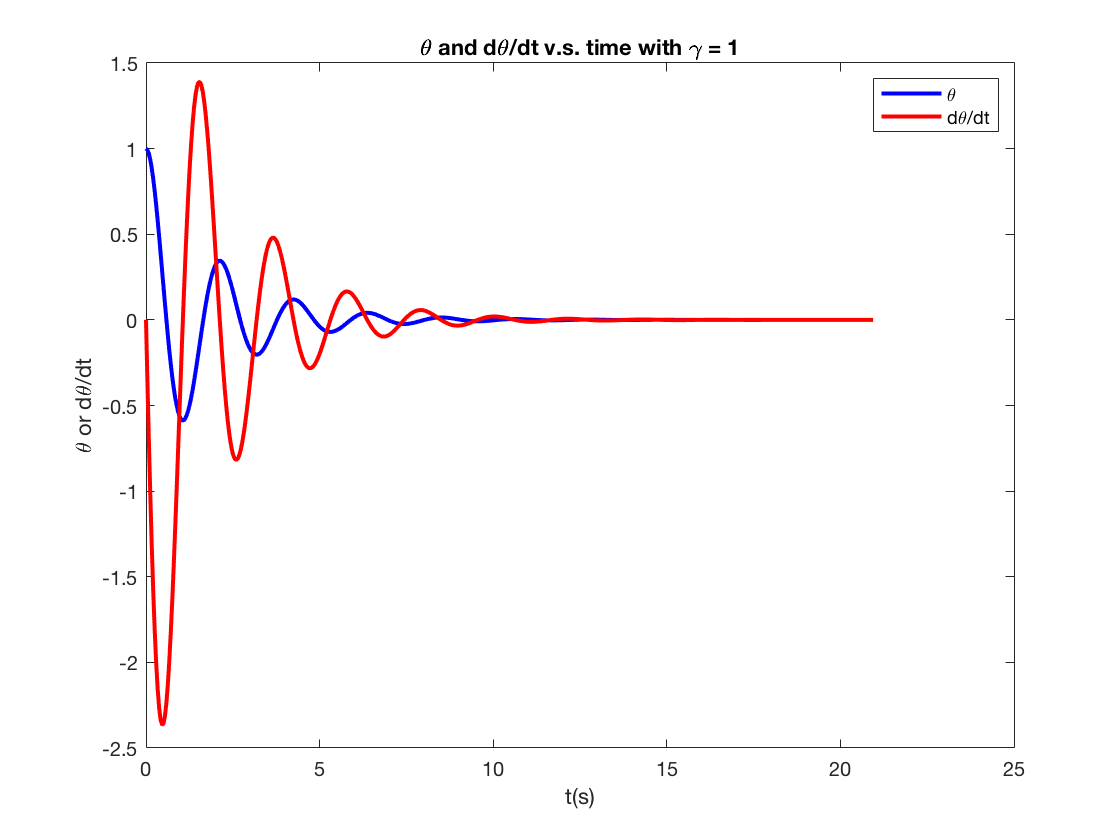

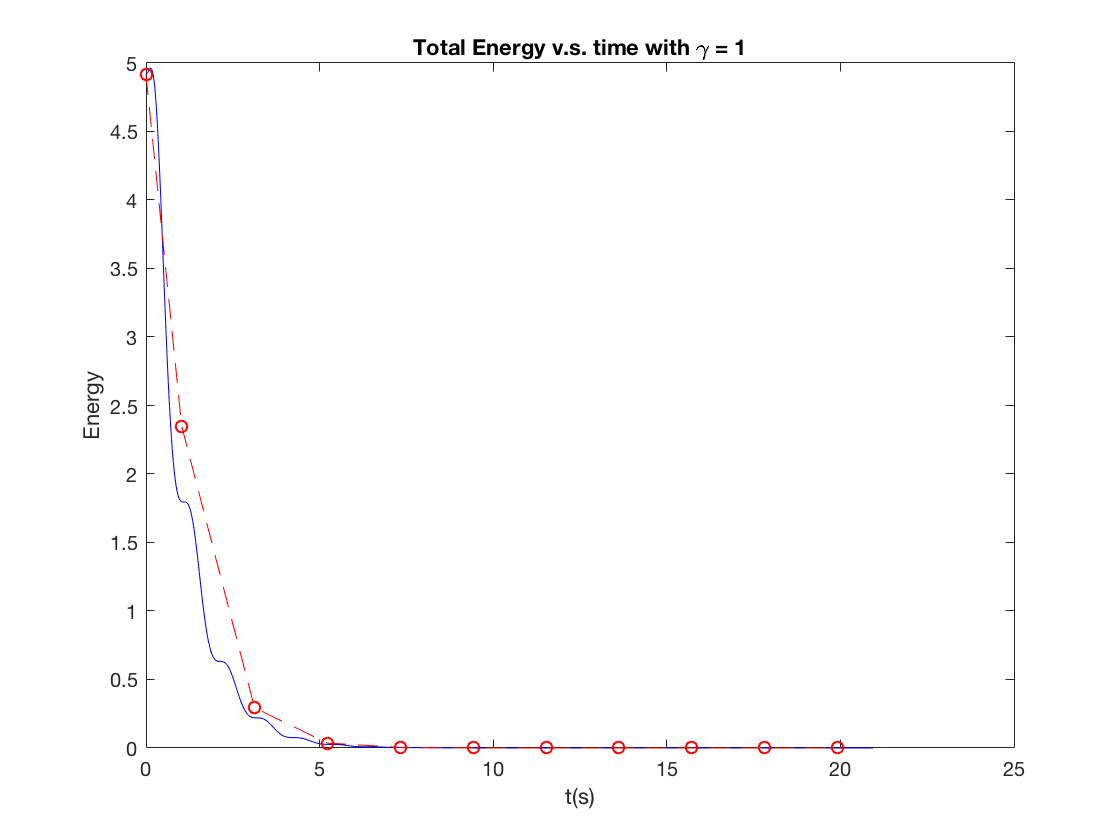

T = 2.0944

T ratio = 1.05, ang. freq. ratio is 0.9524


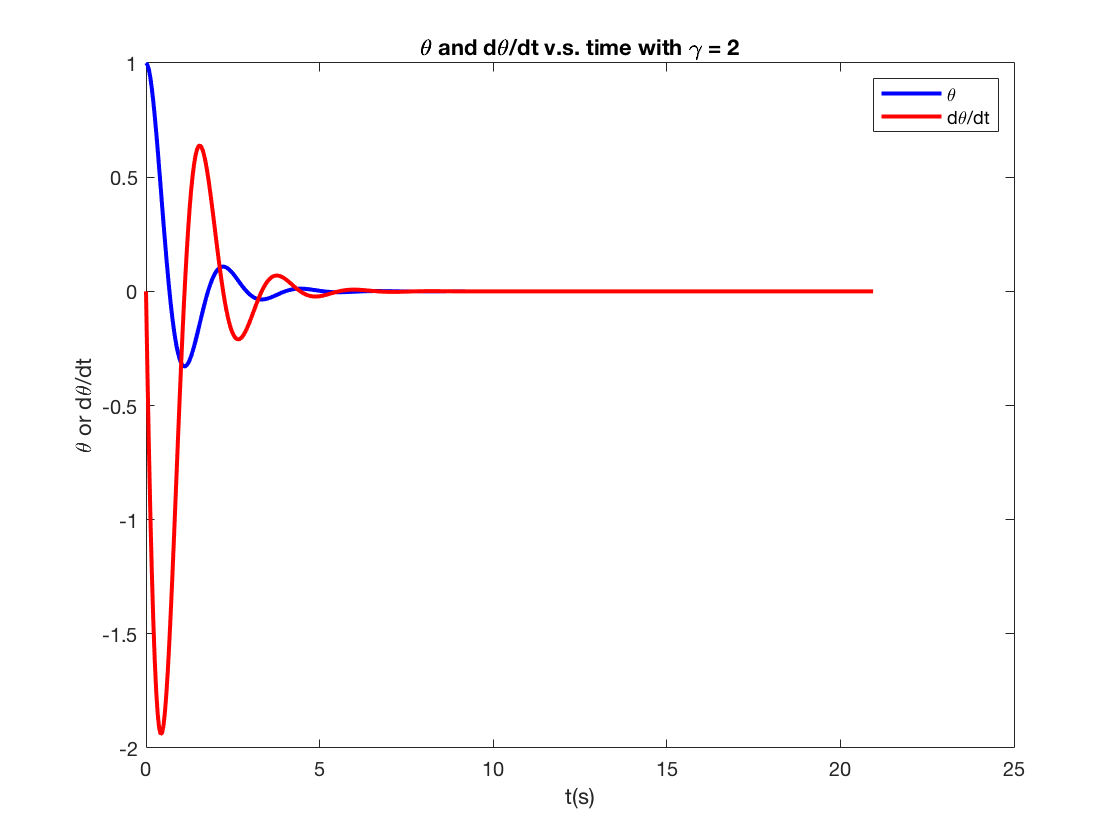

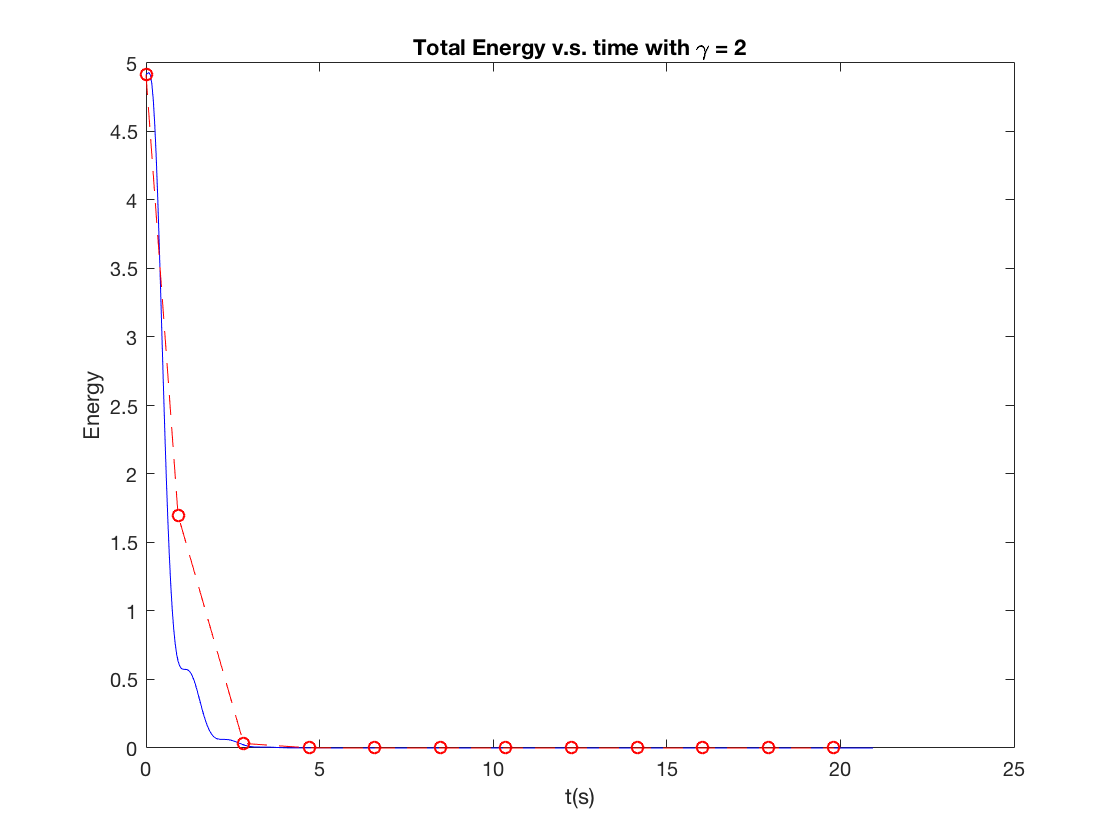

T = 1.9947

T ratio = 1, ang. freq. ratio is 1


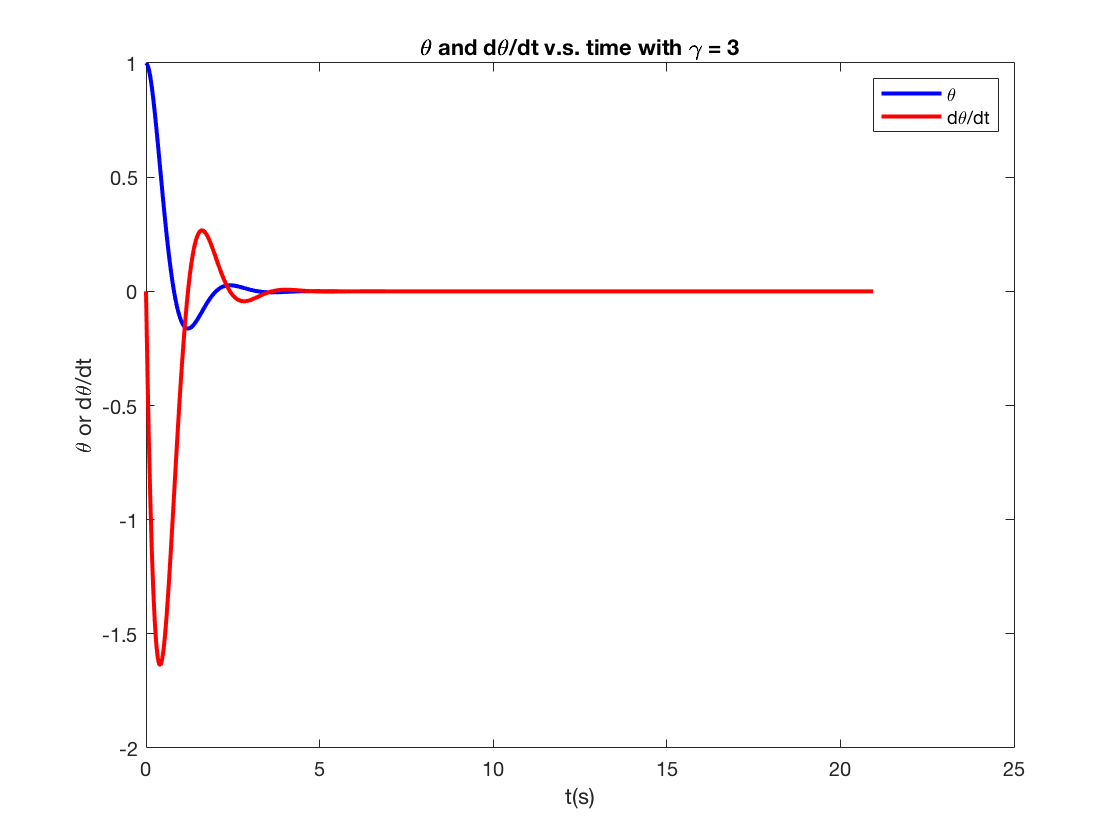

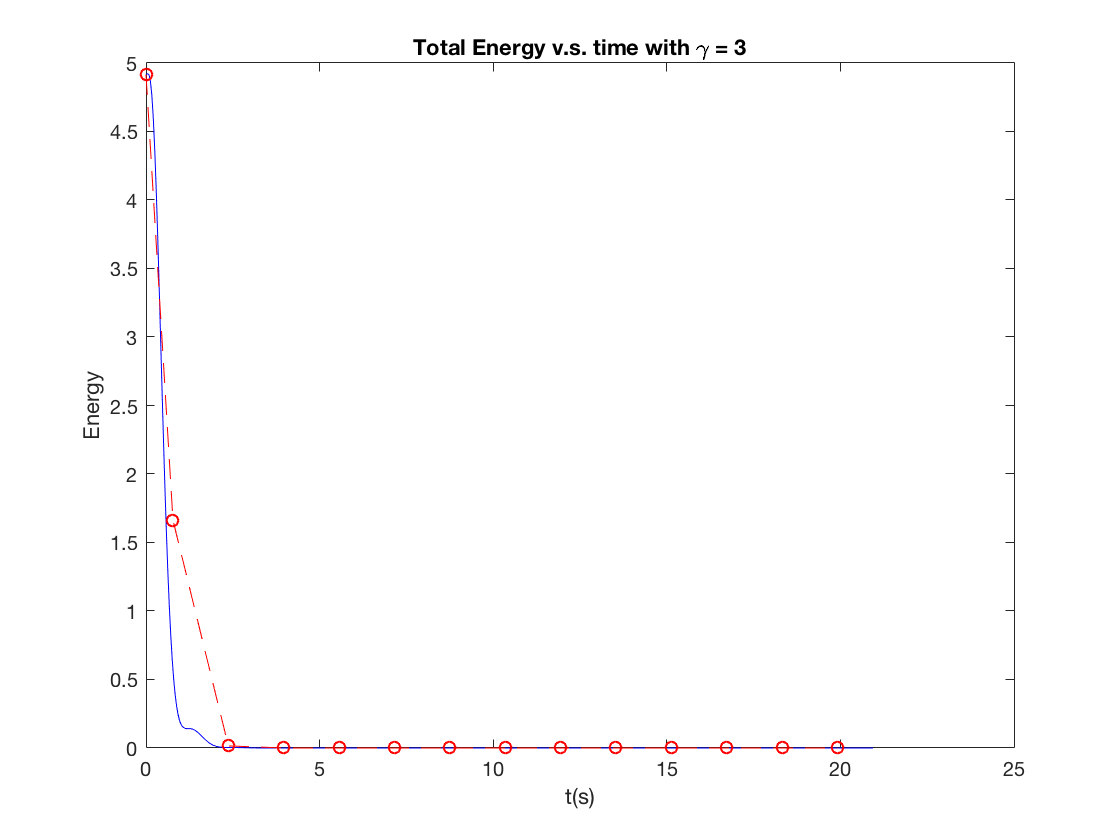

T = 1.6111

T ratio = 0.8077, ang. freq. ratio is 1.238


gamma_list = [0.5,1,2,3];

for i=1:4
    [T, sol] = damped_oscillator(3,gamma_list(i),1,0);
    T
    omega = 2*pi/T;
    disp(['T ratio = ' num2str(T/T_undamped,4) ', ang. freq. ratio is ' num2str(omega...
    /omega_undamped,4)])
end

We expect the period to be larger with larger damping factor. But there is something wrong with gamma = 0.5, it has the same period with gamma = 1.

My result shows, for gamma < 3, larger damping ratio makes period larger and angular frequency smaller. 

Also, the total energy is decreasing, but not uniformly.

## (d)Time-dependence for large damping

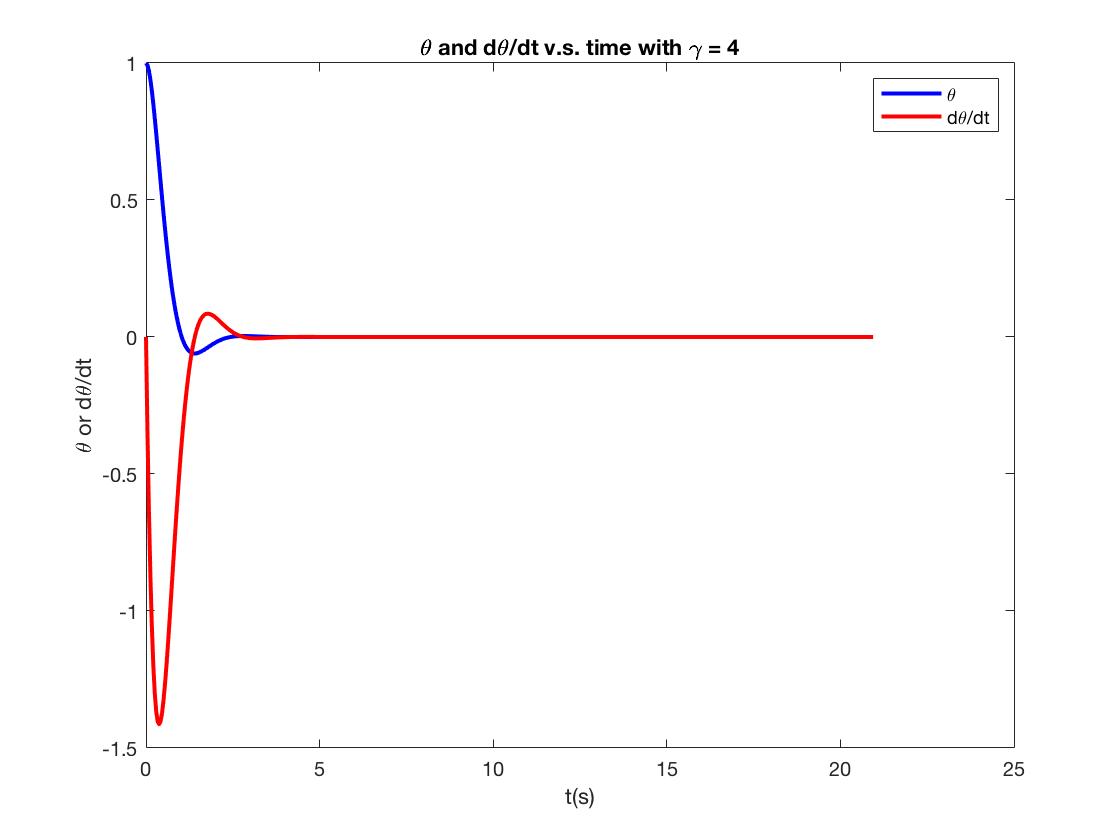

Terminal t = 20.944 s.


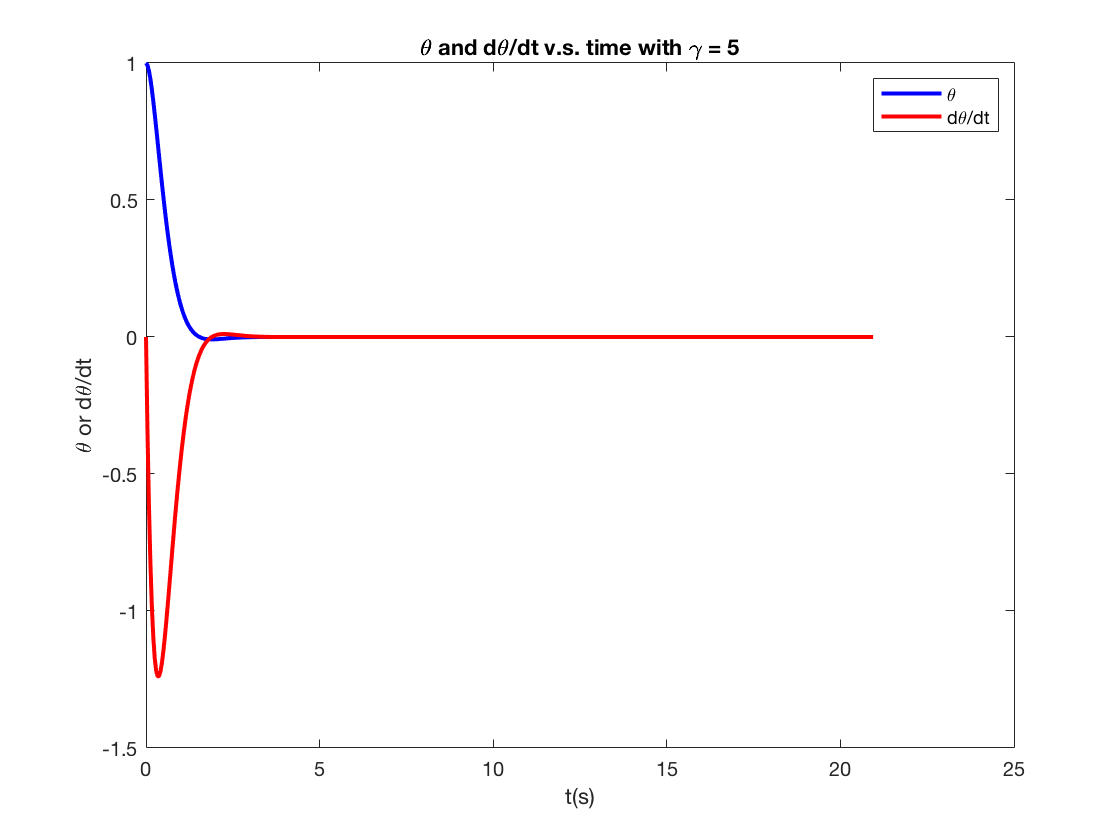

Terminal t = 20.944 s.


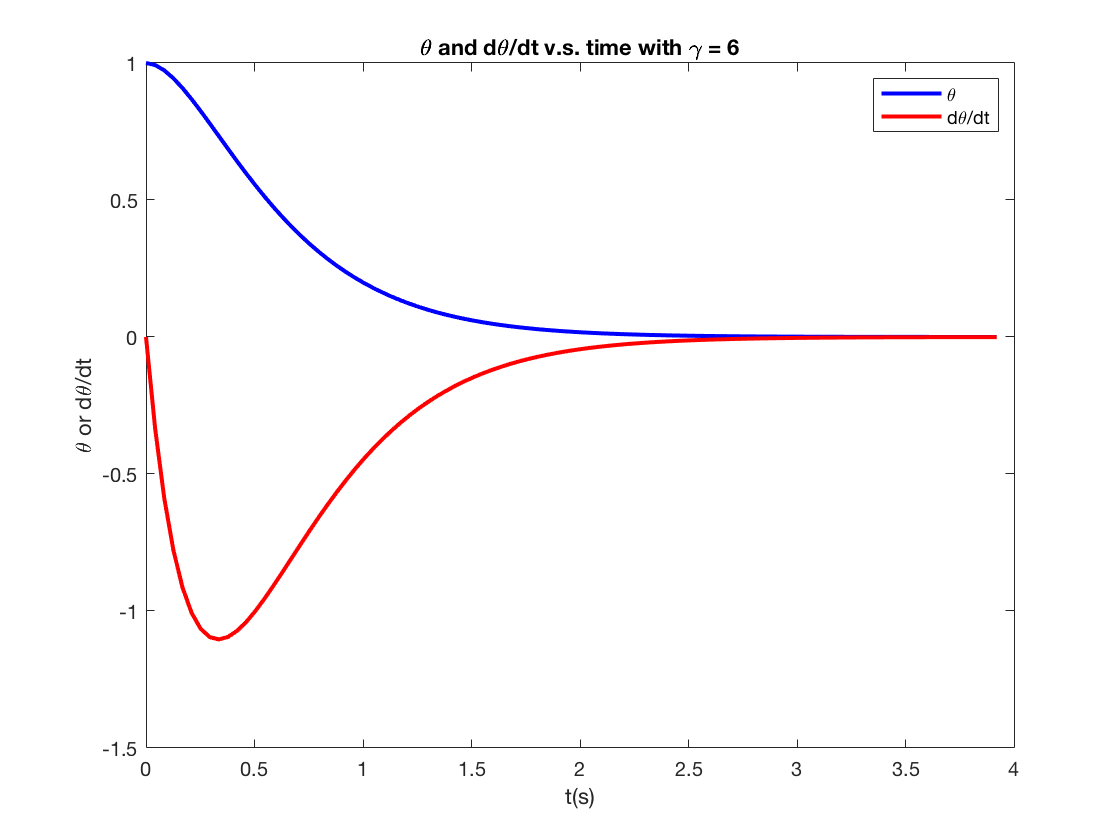

Terminal t = 3.9203 s.


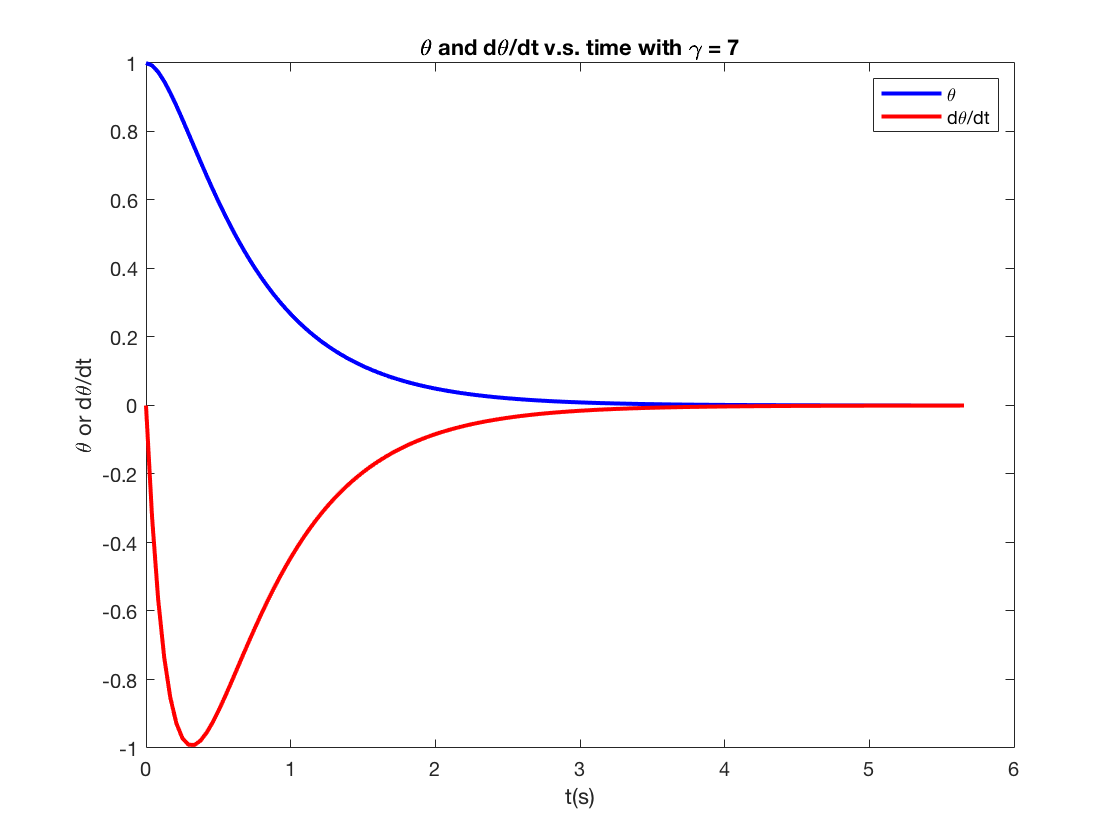

Terminal t = 5.6547 s.


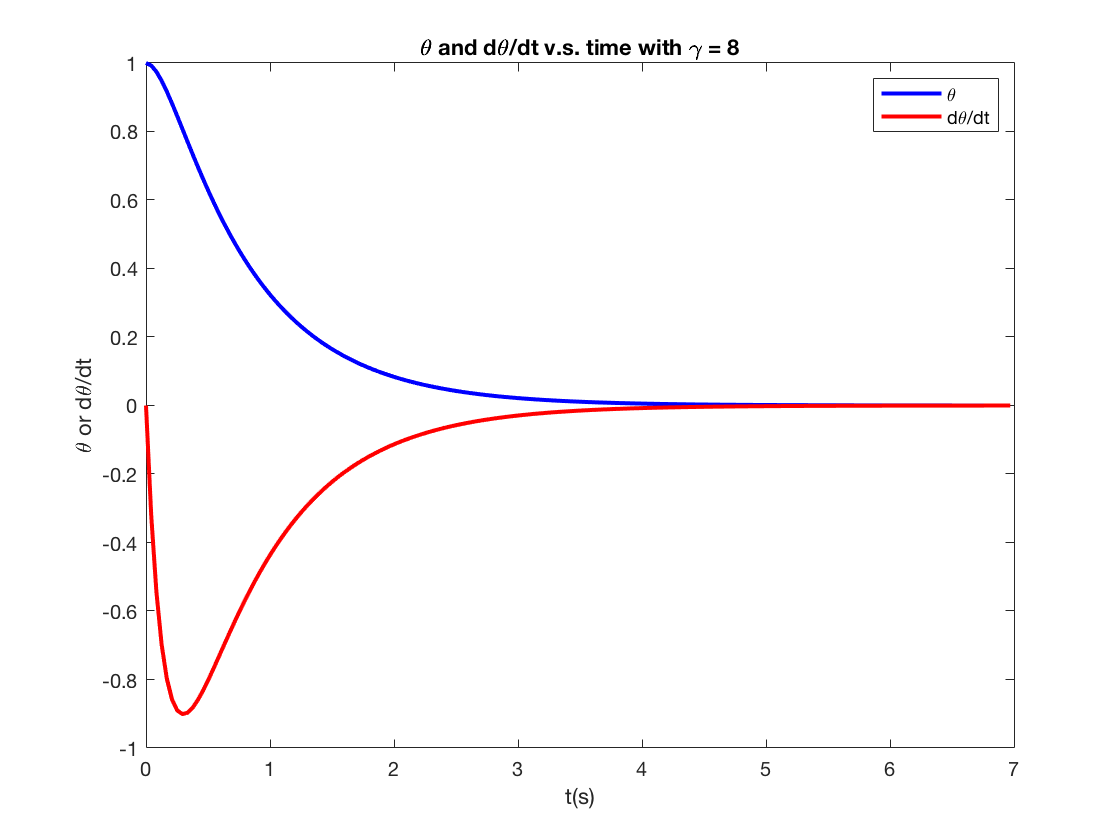

Terminal t = 6.9696 s.


gamma_list = [4,5,6,7,8];

for i=1:5
    [T, sol] = damped_oscillator(3,gamma_list(i),1.,0);
    disp(['Terminal t = ' num2str(sol(end,1)) ' s.'])
    
end

For gamma = 4, 5, there is still oscillation (only one cycle). 

'event' function is triggered for gamma >=  6, to calculate the terminal time.

For gamma > = 6, no oscillation is observed, and larger gamma makes decay slower - terminal time is longer.

## (e) Phase diagram for different gamma

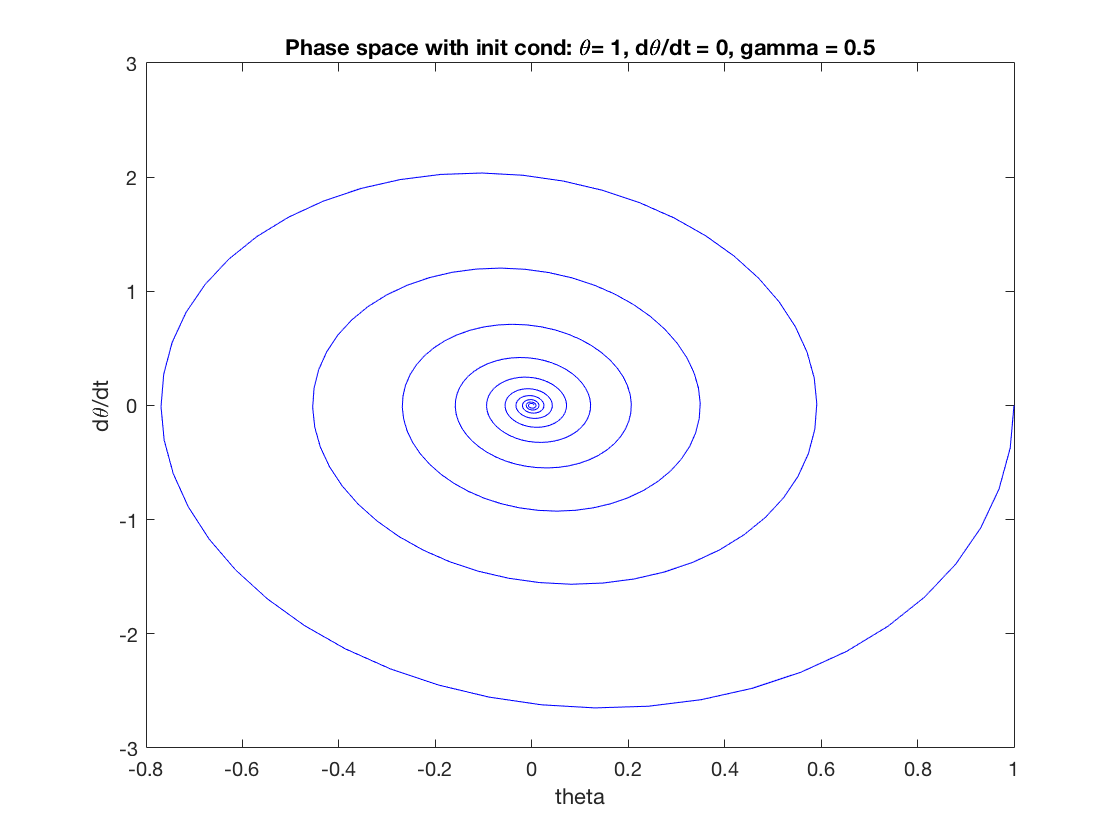

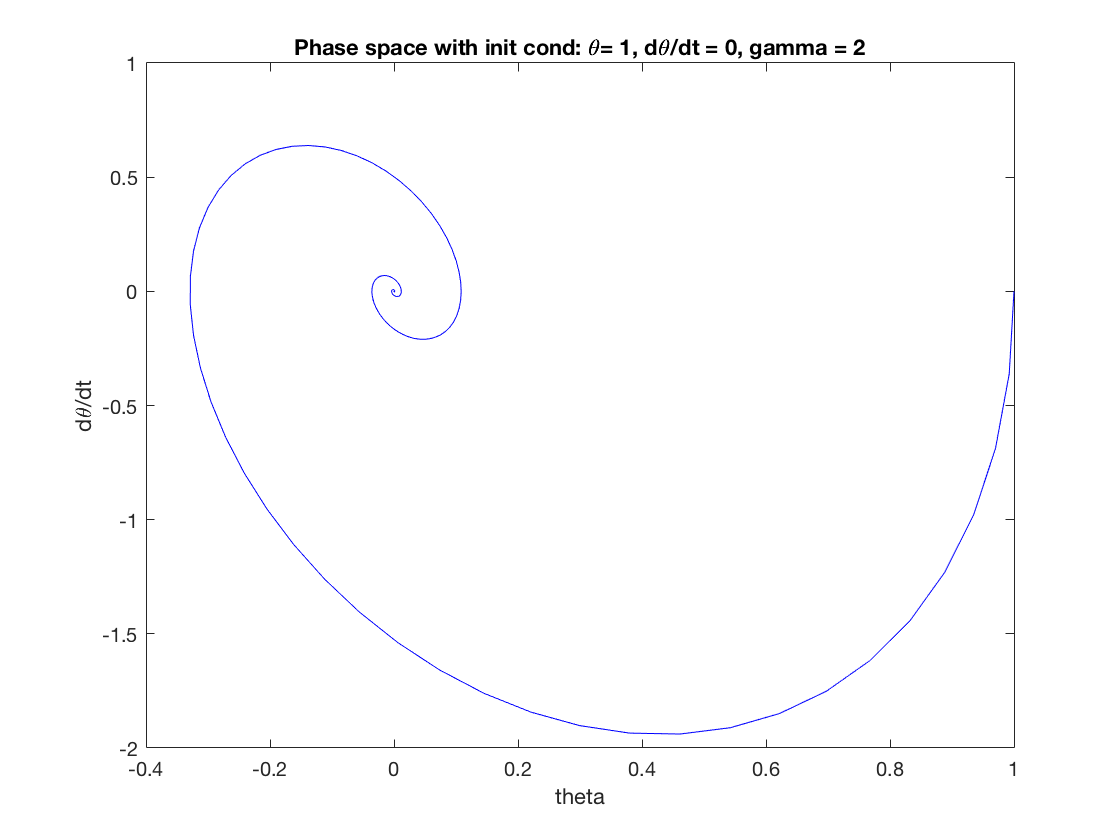

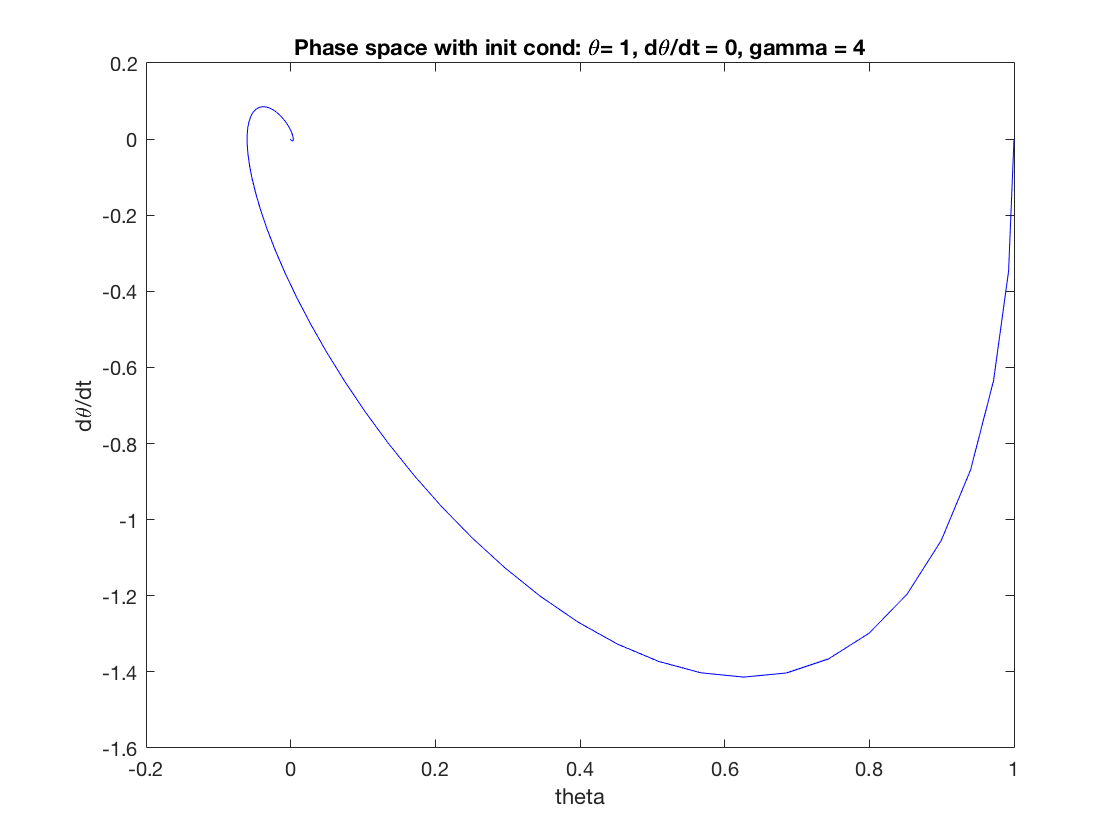

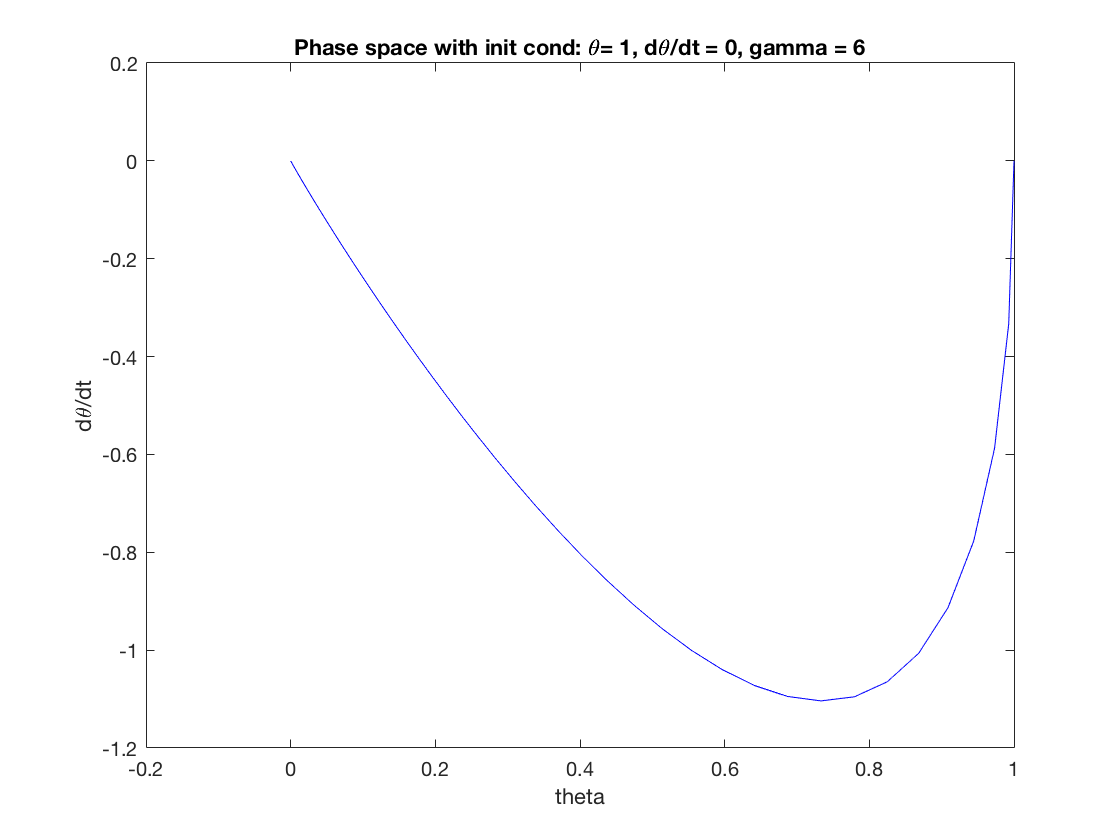

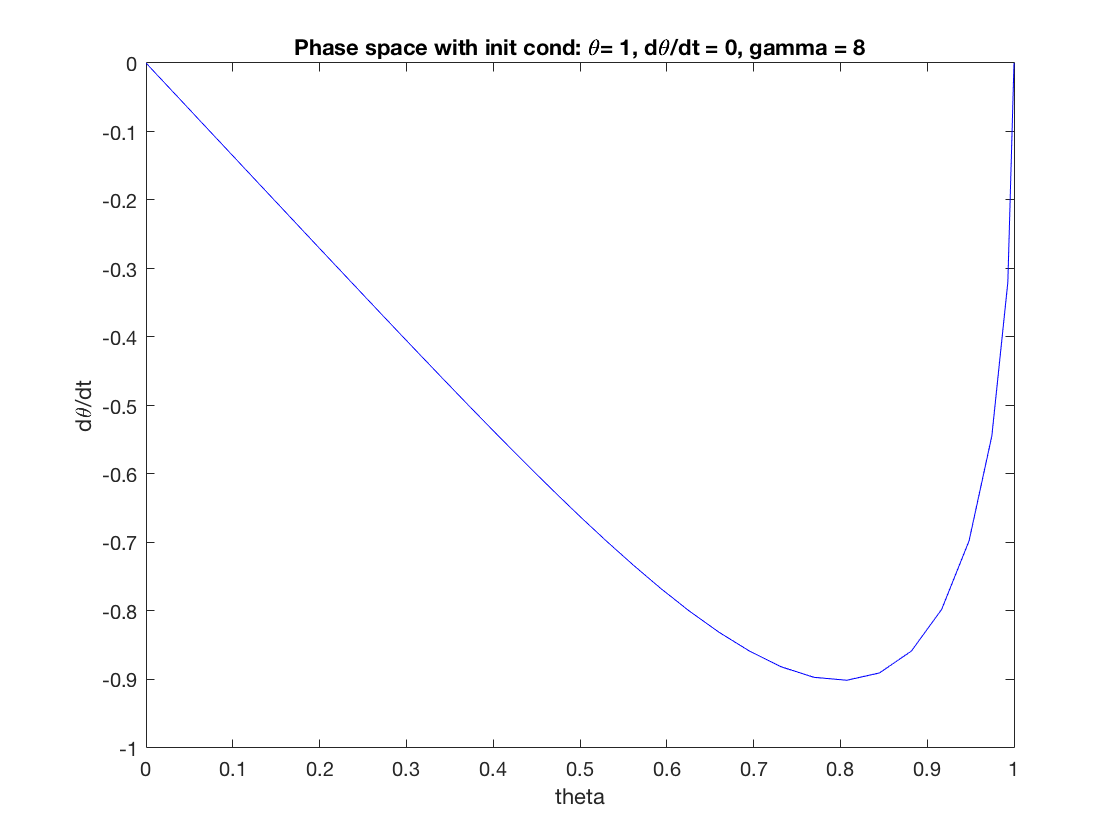

gamma_list = [0.5,2,4,6,8];

for i=1:5
    [T, sol] = damped_oscillator(3,gamma_list(i),1.,0.,0);
    figure
    plot(sol(:,2),sol(:,3),'b')
    title(['Phase space with init cond: \theta= 1, d\theta/dt = 0, gamma = ' num2str(gamma_list(i))])
    %xlim([-2,2])
    %ylim([-4,4])
    xlabel('theta')
    ylabel('d\theta/dt')
end

Qualitative features of phase diagram depends on gamma. If gamma is not big enough, pendulum will still oscillate and then come back to equilibrium - a swirl shape in phase diagram. If gamma is large(compared to omega0), pendulum will come back to equilibrium slowly without oscillation - a direct path to (0,0).